# Entregable 3 - RETO

**Alexia Giselle Paz Jasso | A01635557**

**Diego Curiel Castellanos | A01640372**

**Santiago Vera Espinoza  | A01641585**

clc;
clear;
clf;

hold on;
axis equal;

%   Dimensiones placa positiva
a1 = 2;
l1 = 10;
h1 = 10;

%   Dimensiones placa negativa
a2 = 2;
l2 = 6;
h2 = 6;

%   Distancia entre placas
d = 20;

%   Activadores
qvr = true;    % Activa el quiver para todo el código
qvr3d = true;  % Activa el quiver en 3D

Graficación de placas

dl = abs(l1- l2)/2;
dh = abs(h1 - h2)/2;

% Posiciones Placas

dx1 = 0; % Coordenadas en x para la placa 1
dy1 = 0; % Coordenadas en y para la placa 1
dz1 = 0; % Coordenadas en z para la placa 1

dx2 = a1 + d;   % Coordenadas en x para la placa 1
dy2 = 0 + dl;   % Coordenadas en y para la placa 1
dz2 = 0;        % Coordenadas en z para la placa 1

if h1>h2 % La diferencia de altura para centrar las placas
    dz2 = dz2 + dh;
    pmh = h1/2;
else
    dz1 = dz1 + dh;
    pmh = h2/2;
end

% Ejes

distp = 10;

% Definir límites
xmin = -distp;
xmax = dx2 + a2 + distp;
ymin = -distp;
ymax = dy2 + l2 + distp;
zmin = -distp;
zmax = dz2 + h2 + distp + dh;

verticesR1 = [0,l1,0;  % V1
              a1,l1,0;  % V2
              a1,0,0;  % V3
              0,0,0;  % V4
              0,l1,h1;  % V5
              a1,l1,h1;  % V6
              a1,0,h1;  % V7
              0,0,h1]; % V8

verticesR2 = [0,l2,0;  % V1
              a2,l2,0;  % V2
              a2,0,0;  % V3
              0,0,0;  % V4
              0,l2,h2;  % V5
              a2,l2,h2;  % V6
              a2,0,h2;  % V7
              0,0,h2]; % V8

verticesR1 = offset3D(verticesR1, dx1, dy1, dz1);
verticesR2 = offset3D(verticesR2, dx2, dy2, dz2);

carasR = [1 2 6 5;   % Cara 1
          2 3 7 6;   % Cara 2
          3 4 8 7;   % Cara 3
          4 8 5 1;   % Cara 4
          5 6 7 8;   % Cara 5
          1 2 3 4];  % Cara 6

% Graficación de las placas
patch('Faces', carasR, 'Vertices', verticesR1, 'Facecolor', 'r');
patch('Faces', carasR, 'Vertices', verticesR2, 'Facecolor', 'b');
view(30,30);
axis([xmin, xmax, ymin, ymax, zmin, zmax]);

Cálculo de campo eléctrico

k = 8.99e9; % Constante eléctrica
Cd = 1;

if qvr3d == 1 % Creación de la malla
    [xGrid, yGrid, zGrid] = meshgrid(xmin:4:xmax, ymin:4:ymax, zmin:4:zmax);
elseif qvr3d == 0
    [xGrid, yGrid] = meshgrid(xmin:4:xmax, ymin:4:ymax);
    zGrid = xGrid*0 + pmh;
end

%----------------Carga Neg 1-------------------- azul

Qn1 = -20;

dxn1 = dx2;
dyn1 = dy2;
dzn1 = 0 + h2/2;

Rxn1 = xGrid - dxn1;
Ryn1 = yGrid - dyn1;
Rzn1 = zGrid - dzn1;
Rn1 = sqrt(Rxn1.^2 + Ryn1.^2 + Rzn1.^2).^3;

Exn1 = k.*Qn1.*Rxn1./Rn1; % Campos eléctricos en x
Eyn1 = k.*Qn1.*Ryn1./Rn1; % Campos eléctricos en y
Ezn1 = k.*Qn1.*Rzn1./Rn1; % Campos eléctricos en z

%----------------Carga Pos 1-------------------- rojo

Qp1 = 20;

dxp1 = dx1 + a1;
dyp1 = dy1;
dzp1 = 0 + h1/2;

Rxp1 = xGrid - dxp1;
Ryp1 = yGrid - dyp1;
Rzp1 = zGrid - dzp1;
Rp1 = sqrt(Rxp1.^2 + Ryp1.^2 + Rzp1.^2).^3;

Exp1 = Exn1 + k.*Qp1.*Rxp1./Rp1;
Eyp1 = Eyn1 + k.*Qp1.*Ryp1./Rp1;
Ezp1 = Ezn1 + k.*Qp1.*Rzp1./Rp1;

%----------------Carga Neg 2-------------------- azul

Qn2 = -20;

dxn2 = dx2 + a2;
dyn2 = dy2 + l2;
dzn2 = 0 + h2/2;

Rxn2 = xGrid - dxn2;
Ryn2 = yGrid - dyn2;
Rzn2 = zGrid - dzn2;
Rn2 = sqrt(Rxn2.^2 + Ryn2.^2 + Rzn2.^2).^3;

Exn2 = Exp1 + k.*Qn2.*Rxn2./Rn2; % Campos eléctricos en x
Eyn2 = Eyp1 + k.*Qn2.*Ryn2./Rn2; % Campos eléctricos en y
Ezn2 = Ezp1 + k.*Qn2.*Rzn2./Rn2; % Campos eléctricos en z

%----------------Carga Pos 2-------------------- rojo

Qp2 = 20;

dxp2 = dx1 + a1;
dyp2 = dy1 + l1;
dzp2 = 0 + h1/2;

Rxp2 = xGrid - dxp2;
Ryp2 = yGrid - dyp2;
Rzp2 = zGrid - dzp2;
Rp2 = sqrt(Rxp2.^2 + Ryp2.^2 + Rzp2.^2).^3;

Exp2 = Exn2 + k.*Qp2.*Rxp2./Rp2; % Campos eléctricos en x
Eyp2 = Eyn2 + k.*Qp2.*Ryp2./Rp2; % Campos eléctricos en y
Ezp2 = Ezn2 + k.*Qp2.*Rzp2./Rp2; % Campos eléctricos en z

%--------------+++Total 1+++--------------------

E = sqrt(Exp2.^2 + Eyp2.^2 + Ezp2.^2);

i = Exp2./E; % Componente i
j = Eyp2./E; % Componente j
k = Ezp2./E; % Componente k

if qvr3d == 0 % Cancelación del eje z
    k = k.*0;
end

if qvr == 1 % Graficación de las flechas de campo
    quiver3(xGrid, yGrid, zGrid, i, j, k);
end

Glóbulos y cargas de glóbulos

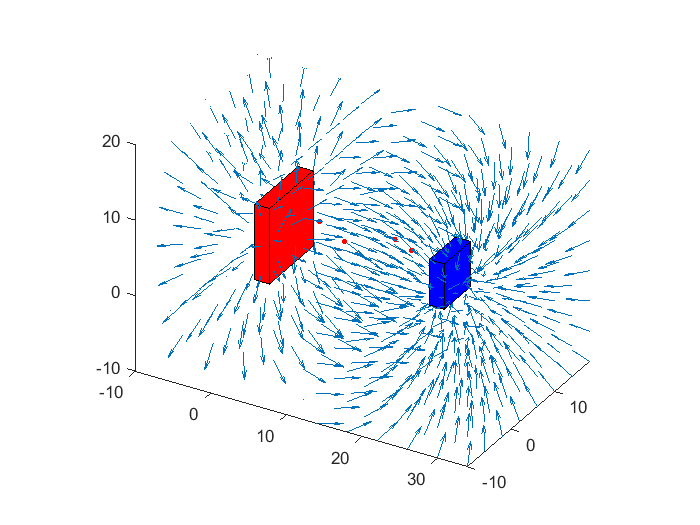

Campo electrico glóbulo 1: 5319526627218.726


   5.3195e+12



Campo electrico glóbulo 2: 1114610196389.614


   1.1146e+12



Campo electrico glóbulo 3: 5319526627219.017


   5.3195e+12



Campo electrico glóbulo 4: 6040042999193.776


   6.0400e+12



Campo electrico glóbulo 5: 642712116445.9946


   6.4271e+11



nG = 5; % Número de glóbulos

% Posición aleatorias de los glóbulos en el rango indicado
posXG = (randi([(0 + a1)*100, (a1 + d)*100], nG, nG))/100;
posYG = (randi([dl * 100, l1 * 100], nG, nG))/100;

% Radios esferas
RadioGlobulo = 0.25;
RadioCarga = 0.05;

% Coordenadas del glóbulo con número de polígonos igual a 10
[xG, yG, zG] = sphere(10);
xG = xG * RadioGlobulo;
yG = yG * RadioGlobulo;
zG = zG * RadioGlobulo;

[xC, yC, zC] = sphere(10);
xC = xC * RadioCarga;
yC = yC * RadioCarga;
zC = zC * RadioCarga;

% Distancia aleatoria desde el centro a una de las cargas
distC = (randi([(RadioCarga) * 1000, ...    % mínimo
               (RadioGlobulo) * 1000], ...  % máximo
               nG, 1))/1000;                % tam vector

% Cargas
QCp = 5;
QCn = -5;
k2 = 8.99e9;

% ++++++++++++++Promedio Umbral+++++++++++++++

% Promedio Umbral es el promedio entre la mayor carga posible
% y la menor. Si un glóbulo excede esta medida, se le considera
% como que está infectado.

%       Límite 1
L1RxCp = RadioGlobulo - RadioCarga;
L1RxCn = RadioGlobulo + RadioCarga;

L1R = abs(L1RxCp-L1RxCn);

L1ECp = k2.*QCp./L1R.^2; % Campo eléctrico positivo en el límite 1
L1ECn = k2.*QCn./L1R.^2; % Campo eléctrico negativo en el límite 1

%       Carga total límite 1
L1E = L1ECp - L1ECn;

%       Límite 2 
L2RxCp = RadioCarga;
L2RxCn = RadioGlobulo*2 - RadioCarga;

L2R = abs(L2RxCp-L2RxCn);

L2ECp = k2.*QCp./L2R.^2; % Campo eléctrico positivo en el límite 2
L2R = abs(L2RxCp-L2RxCn);
L2ECn = k2.*QCn./L2R.^2; % Campo eléctrico negativo en el límite 2

%       Carga total límite 2
L2E = L2ECp - L2ECn;

%       Promedio umbral
UE = (L1E + L2E)/2; % Promedio de ambos límites

% ++++++++++++++++++++++++++++++++++++++

contMal = 0; % Contador de glóbulos infectados
vecID = []; % Vector con la dirección en el vector de los glóbulos infectados

for i = 1:nG % Ciclo por cada glóbulo infectado
    
    % Posición de la carga positiva
    Pcpx = posXG(i,1)-RadioGlobulo+distC(i,1);
    Pcpy = posYG(i,1);
    Pcpz = pmh;
    
    % Posición de la carga negativa
    Pcnx = posXG(i)+RadioGlobulo-distC(i);
    Pcny = posYG(i);
    Pcnz = pmh;
      
    RxCp = Pcpx;
    RxCn = Pcnx;
    
    R = sqrt((RxCp-RxCn).^2); % Distancia entre cargas
    
    ECp = k2.*QCp./R.^2; % Fórmula de campo eléctrico positiva
    ECn = k2.*QCn./R.^2; % Fórmula de campo eléctrico negativa
    
    %---------------Carga Total---------------
    E = ECp - ECn;
    
    % Mensaje de salida
    msg = ['Campo electrico glóbulo ',  num2str(i), ': ', num2str(E)];
    disp(msg);
    disp(E);
    
    % Graficación de las esferas
    surf(xG+posXG(i), yG+posYG(i), zG+pmh, ...
        'FaceColor', 'r', 'EdgeColor', 'r', ...
        'FaceAlpha', '0.3');
    surf(xC+Pcpx, yC+Pcpy, zC+Pcpz, ...
        'FaceColor', 'k', 'EdgeColor', 'k');
    surf(xC+Pcnx, yC+Pcny, zC+Pcnz, ...
        'FaceColor', 'k', 'EdgeColor', 'k');
    
    if E>UE % Comparar el campo actual con el campo promedio
        contMal = contMal + 1;
        vecID(contMal) = i;
    end
end

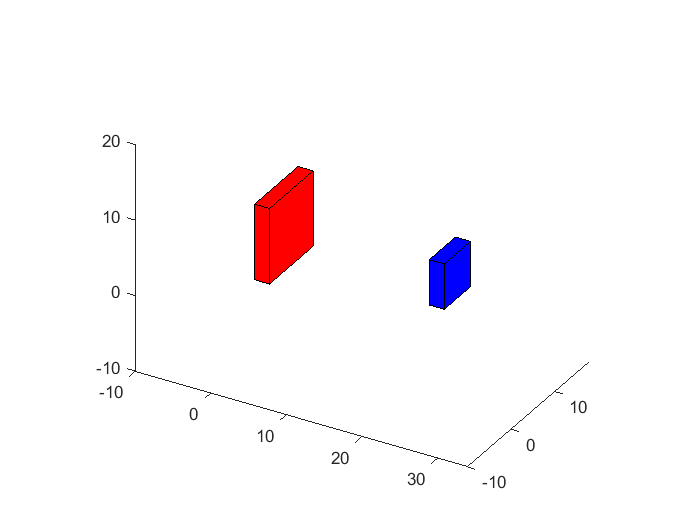


sep = l2/(contMal+1); % Obtener la separacion entre las cargas en la placa negativa
for i = 1:contMal

    id = vecID(i);
    %disp(id);

    % Actualizar las coordenadas
    posXG(id,1) = dx2-RadioGlobulo; 
    posYG(id,1) = dy2 + i*sep;
end

figure; % Separar la figura despues del cambio
hold on;
axis equal;

% Imprimir las placas
patch('Faces', carasR, 'Vertices', verticesR1, 'Facecolor', 'r');
patch('Faces', carasR, 'Vertices', verticesR2, 'Facecolor', 'b');
view(30,30);
axis([xmin, xmax, ymin, ymax, zmin, zmax]);

for id = 1:contMal % Imprimir los glóbulos infectados

    i = vecID(id);

    % Coordenadas carga positiva
    Pcpx = posXG(i,1)-RadioGlobulo+distC(i,1);
    Pcpy = posYG(i,1);
    Pcpz = pmh;
    
    % Coordenadas carga negativa
    Pcnx = posXG(i)+RadioGlobulo-distC(i);
    Pcny = posYG(i);
    Pcnz = pmh;
    
    % Gráficas las esferas
    surf(xG+posXG(i), yG+posYG(i), zG+pmh, ...
        'FaceColor', 'r', 'EdgeColor', 'r', ...
        'FaceAlpha', '0.3');
    surf(xC+Pcpx, yC+Pcpy, zC+Pcpz, ...
        'FaceColor', 'k', 'EdgeColor', 'k');
    surf(xC+Pcnx, yC+Pcny, zC+Pcnz, ...
        'FaceColor', 'k', 'EdgeColor', 'k');
end


% Cantidad de glóbulos infectados
msg = ['Hubo ',  num2str(contMal), ' glóbulos infectados de ', num2str(nG)];

% Paciente infectado o no
if contMal >= nG/2
    disp('El paciente está infectado.');
else
    disp('El paciente no está infectado.');
end

El paciente está infectado.


disp(msg);

Hubo 3 glóbulos infectados de 5
